# **demo11 of Im2mesh package**

demo11 - Find node sets at the interface and boundary

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Kumamon

Let's start. Import image kumamon.tif.

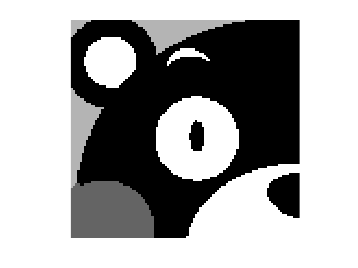

im = imread('kumamon.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

opt = [];
opt.tolerance = 1;
[ vert, tria, tnum, vert2, tria2 ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                 96                125
          8                107                211


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                153                125
         10                178                690
         15                180                714


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------



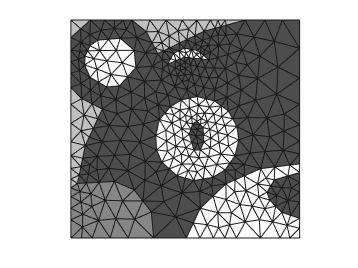

plotMeshes( vert, tria, tnum )

## Scale node coordinates

% scale
dx = 1;

% node coordinates for linear element
vert = vert * dx;

% node coordinates for quadratic element
vert2 = vert2 * dx;

## Represent mesh in an alternative way

% get node coordinates and elements from mesh using function getNodeEle
[ nodecoor_list, nodecoor_cell, ele_cell ] = getNodeEle( vert, tria, tnum );

[ nodecoor_list, nodecoor_cell, ele_cell ] is an alternative way to represent the triangular mesh. This format is useful for importing the mesh into commercial finite element software. 

nodecoor_list is node coordinates, N-by-3 array.

nodecoor_cell is a 1-by-P cell array. nodecoor_cell{i} represents the node numbering and node coordinates in the i-th phase. nodecoor_cell{i} is a M-by-3 array.

ele_cell is a 1-by-P cell array. ele_cell{i} represent elements in the i-th phase. ele_cell{i} is a T-by-4 array.

For quadratic elements, we can use the same function.

## Node sets at interface and boundary

Here, we are interested in nodes at interface and boundary, which can be used to define interface and boundary condition.

We use function getInterf to find nodes at the interface between different phases. 

interfnode_cell = getInterf( nodecoor_cell );

interfnode_cell is a N-by-N cell array. interfnode_cell{i,j} stores the interfacial node numbering between the i-th phase and the j-th phase. interfnode_cell{i,j} is column vector. If the i-th phase and the j-th phase have no contact,  interfnode_cell{i,j} would be empty.

We use function getBCNode to find nodes at the boundary.

[ xmin_node_cell, xmax_node_cell, ...
  ymin_node_cell, ymax_node_cell ] = getBCNode( nodecoor_cell );

xmin_node_cell, xmax_node_cell, ymin_node_cell, ymax_node_cell are the node numbering of nodes that located at x min, x max, y min, y max. They are 1-by-p cell array. For example, xmin_node_cell{i} is the node numbering of nodes in the i-th phase that located at x min. xmin_node_cell{i} is a column vector.

## Display nodes at the interface

For example, we are interested in the nodes at the interface between the 1st phase and the 3rd phase. We can call it interfnode_AC. interfnode_AC is column vector, recording the node numbering.

interfnode_AC = interfnode_cell{1,3};

Let plot them.

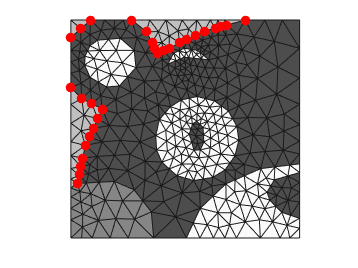

figure;
hold on; 
axis image off;

% -------------------------------------
% show mesh
tvalue = unique( tnum );
num_phase = length( tvalue );

% setup color
if num_phase == 1
    col = 0.98;
elseif num_phase > 1
    col = 0.3: 0.68/(num_phase-1): 0.98;
else
    error('num_phase < 1')
end

for i = 1: num_phase
    phasecode = tvalue(i);
    patch('faces',tria( tnum==phasecode, 1:3 ),...
        'vertices',vert, ...
        'facecolor',[ col(i), col(i), col(i) ], ...
        'edgecolor',[.1,.1,.1]);
end

% -------------------------------------
% show nodes
for i=1:length( interfnode_AC )
    idx = interfnode_AC(i);
    x = nodecoor_list( nodecoor_list(:,1)==idx, 2 );
    y = nodecoor_list( nodecoor_list(:,1)==idx, 3 );
    plot(x,y,'r.','MarkerSize',15);
    
end
% -------------------------------------
hold off

Very good!

## Display nodes at the boundary

For example, we are interested in the nodes of the 1st phase that located at the boundary (y max). We can call it ymax_node_A. ymax_node_A is column vector, recording the node numbering.

ymax_node_A = ymax_node_cell{3};

Let plot them.

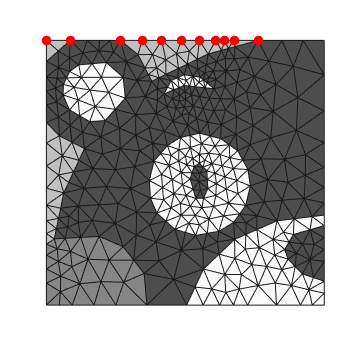

figure;
hold on; 
axis image off;

% -------------------------------------
% show mesh
tvalue = unique( tnum );
num_phase = length( tvalue );

% setup color
if num_phase == 1
    col = 0.98;
elseif num_phase > 1
    col = 0.3: 0.68/(num_phase-1): 0.98;
else
    error('num_phase < 1')
end

for i = 1: num_phase
    phasecode = tvalue(i);
    patch('faces',tria( tnum==phasecode, 1:3 ),...
        'vertices',vert, ...
        'facecolor',[ col(i), col(i), col(i) ], ...
        'edgecolor',[.1,.1,.1]);
end

% -------------------------------------
% show nodes
for i=1:length( ymax_node_A )
    idx = ymax_node_A(i);
    x = nodecoor_list( nodecoor_list(:,1)==idx, 2 );
    y = nodecoor_list( nodecoor_list(:,1)==idx, 3 );
    plot(x,y,'r.','MarkerSize',15);
    
end
% -------------------------------------
hold off

Very good!

opt = [];
opt.tf_printMaxMinNode = 0;
opt.tf_printInterfNode = 0;

opt.user_nodeSet{1} = {'name1', [2 5 8]};
opt.user_nodeSet{2} = {'name2', [36 23 56 80]};
printInp2d( vert, tria, tnum, [], [], [], opt );

printInp2d Done! Check the inp file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo